# Problem 4

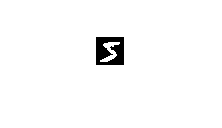

%%% Loading 60000 training set and labels %%%
data = load('../data/mnist.mat');
images = getfield(data,'digits_train');
float_images = cast(images,'double');
labels = getfield(data,'labels_train');

%%% Visuallisation of images %%%
axis equal;
imshow(float_images(:,:,1));

% isfloat(float_images);

zero_indices = find(labels==0);
zeroes = images(:,:,zero_indices);
one_indices = find(labels==1);

for i = 0:9
    indices_digit_i = find(labels==i);
    images_digit_i = float_images(:,:,indices_digit_i);
    imgvec_digit_i = reshape(images_digit_i,28*28,1,[]);
    freq = size(imgvec_digit_i,3);
    
    %%% PART 1 %%%%
    % (i)
    % mean calulation:   E[X]
    mean_digit_i = sum(imgvec_digit_i,3)/freq;
   
    % (ii)
    % covariance calculation:  E[XX^T] - E[X](E[X])^T
    covariance_digit_i = zeros(28*28,28*28,'double');
    for j = 1:freq
        covariance_digit_i = covariance_digit_i + imgvec_digit_i(:,:,j)*imgvec_digit_i(:,:,j).';
    end
    covariance_digit_i = covariance_digit_i/freq - mean_digit_i*mean_digit_i.';
    
    % (ii)
    % Principal mode of variation
    [Q,D] = eig(covariance_digit_i);
    [d,ind] = sort(diag(D),'descend');
    lambda = d(1)
    v = Q(:,ind(1))
    
    figure
    %%%% PART 2 %%%
    plt = plot(d);
    xlim([0,100])
    drawnow
    saveas(plt,'plot' + string(i),'jpg')
    
    %%% PART 3 %%%
    % (i)
    img1 = reshape(mean_digit_i - sqrt(lambda).*v,28,28);
    
    % (ii)
    img2 = reshape(mean_digit_i,28,28);

    % (iii)
    img3 = reshape(mean_digit_i + sqrt(lambda).*v,28,28);
    
    figure
    img = imshow([img1 img2 img3]);
    drawnow
    saveas(img,string(i),'jpg')
end

lambda = 5.6716e+05

v =          0
         0
         0
         0
         0
         0
         0
         0
    0.0000
         0
